**Equilibrium and Stability Analysis of the Hock-Weil Model:**

This script analyzes the long-term behavior of the system by focusing on the dependency ratios $y$ (Youth/Workers) and $o$ (Elderly/Workers). The other state variables 

clear; clc; close all;

Load Parameters:

P = get_parameters();

% Recalculate target psi to ensure we are analyzing the corrected model
disp(['Analyzing stability for Fertility Preference parameter psi = ', num2str(P.psi_base)]);

Analyzing stability for Fertility Preference parameter psi = 0.061017


Define the Ratio ODE System:

We derive these from the original stock equations, derived in Hock & Weil (2012).

Define the system as an anonymous function:

**Inputs:**

- $t$ - Time

- $X$ - State Vector $\left\lbrack \begin{array}{c}
y\\
o
\end{array}\right\rbrack$

ratio_ode = @(x) get_ratio_derivatives(x, P);

Find Equilibrium Point Numerically:

We look for points where $\frac{dy}{dt}=0$ and $\frac{do}{dt}=0$.

We use $fsolve$ starting from an initial guess.

guess = [0.5; 0.3]; 
options = optimoptions('fsolve', 'Display', 'off');

[eq_point, fval] = fsolve(ratio_ode, guess, options);

y_star = eq_point(1);
o_star = eq_point(2);

% Calculate economic variables at equilibrium
tau_star = (P.alpha * y_star + P.beta * o_star) / (1 + P.alpha * y_star + P.beta * o_star);
n_star   = P.psi_base * (1 - tau_star);

fprintf('--- Equilibrium Results ---\n');

--- Equilibrium Results ---


fprintf('Steady State Youth Ratio (y*): %.4f\n', y_star);

Steady State Youth Ratio (y*): 0.7692


fprintf('Steady State Old Ratio   (o*): %.4f\n', o_star);

Steady State Old Ratio   (o*): 0.2680


fprintf('Steady State Tax Rate    (t*): %.2f%%\n', tau_star*100);

Steady State Tax Rate    (t*): 16.50%


fprintf('Steady State Fertility   (n*): %.4f\n', n_star);

Steady State Fertility   (n*): 0.0510


Stability Analysis (Eigenvalues):

We compute the Jacobian Matrix $J$ at the equilibrium point.

$J=\left\lbrack \begin{array}{cc}
\frac{{\mathrm{dy}}^* }{\mathrm{dy}} & \frac{{\mathrm{dy}}^* }{\mathrm{do}}\\
\frac{{\mathrm{do}}^* }{\mathrm{dy}} & \frac{{\mathrm{do}}^* }{\mathrm{do}}
\end{array}\right\rbrack$.

% We use a simple finite difference method to get the Jacobian numerically
delta = 1e-6;
J = zeros(2,2);
F0 = ratio_ode(eq_point);

% Perturb y
F_y = ratio_ode([y_star + delta; o_star]);
J(:,1) = (F_y - F0) / delta;

% Perturb o
F_o = ratio_ode([y_star; o_star + delta]);
J(:,2) = (F_o - F0) / delta;

disp('--- Jacobian Matrix at Equilibrium ---');

--- Jacobian Matrix at Equilibrium ---


disp(J);

   -0.1090   -0.0191
   -0.0134   -0.0829




eigenvalues = eig(J);
disp('--- Eigenvalues ---');

--- Eigenvalues ---


disp(eigenvalues);

   -0.1166
   -0.0753




if all(real(eigenvalues) < 0)
    disp('Result: The equilibrium is STABLE (Sink).');
else
    disp('Result: The equilibrium is UNSTABLE.');
end

Result: The equilibrium is STABLE (Sink).


Phase Plane Visualization:

This visualizes the "basins of attraction" and the flow vectors.

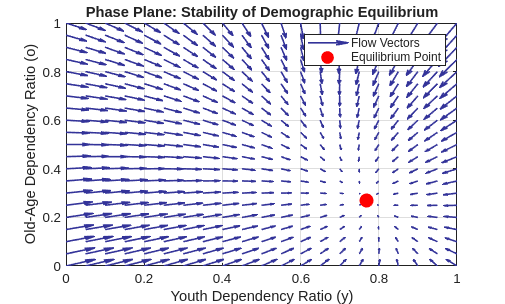

% Create a grid of (y, o) values
[Y_grid, O_grid] = meshgrid(0:0.05:1.0, 0:0.05:1.0);
dY = zeros(size(Y_grid));
dO = zeros(size(O_grid));

% Calculate vector field
for i = 1:numel(Y_grid)
    res = ratio_ode([Y_grid(i); O_grid(i)]);
    dY(i) = res(1);
    dO(i) = res(2);
end

figure('Color','w');
quiver(Y_grid, O_grid, dY, dO, 1.5, 'LineWidth', 1.2, 'Color', [0.2 0.2 0.6]);
hold on;
plot(y_star, o_star, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('Youth Dependency Ratio (y)');
ylabel('Old-Age Dependency Ratio (o)');
title('Phase Plane: Stability of Demographic Equilibrium');
legend('Flow Vectors', 'Equilibrium Point');
grid on;
axis([0 1 0 1]);

**Local Functions:**

function dxdt = get_ratio_derivatives(x, P)
    y = x(1);
    o = x(2); 

Recover Parameters:

    lam_Y = P.lam_Y_base;
    lam_M = P.lam_M_base;
    lam_O = P.lam_O_base;

Economic variables:

    tau = (P.alpha * y + P.beta * o) / (1 + P.alpha * y + P.beta * o);
    n   = P.psi_base * (1 - tau);

Ratio ODEs (Derived from Stock equations):


$$\frac{dy}{dt}=\phi n-(\lambda_Y-\lambda_M)y-\lambda_Y y^2$$


$\frac{do}{dt}=\lambda_M+(\lambda_M-\lambda_O)o-\lambda_Yoy$.

    dy = P.phi * n - (lam_Y - lam_M)*y - lam_Y * y^2;
    do = lam_M + (lam_M - lam_O)*o - lam_Y * y * o;
    
    dxdt = [dy; do];
end